# 4 - Linear Neighbourhood Operations and Gradient-Based Edge Detectors 

clear all;
close all;
clc;

%------------------------------------------------------------

## Simple 1D Gradient Edge Detection 

####  Edge Strength operator

input = [0 0 0 10 200 201 203 198 202 130 90 12];
N=length(input);
diff=input(2:N)-input(1:N-1);% difference operator
absolute_diff=abs(diff); % absolute value
T= 150; %Threshold
edge_map=absolute_diff>=T;

## Convolution Interpretation

h=[0 1 -1]; %mask to create the difference operator using convolution
diff2=conv(h,input);

% moving average of length M
M=3;
h_ma=ones(1,M)./M;
smoothened=conv(h_ma,input);

%second derivative
%       d2(n) = d(n) - d(n-1)
%             = f(n) - f(n-1) - f(n-1) + f(n-2)
%             = f(n) - 2f(n-1) + f(n-2)

h_dd=[1 -2 1];

dd=conv(h_dd,input);

## 2D Edge Detection 

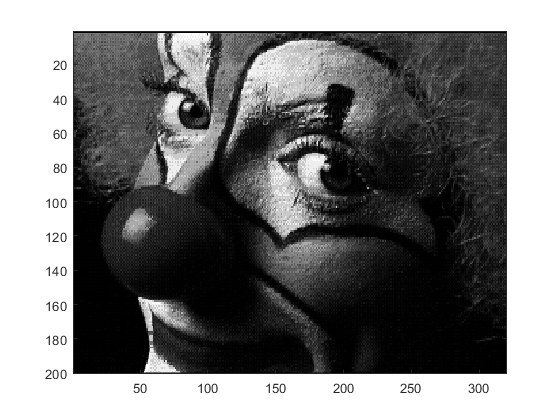

%% load images
load('TestImages.mat'); 
figure;
imagesc(clown);colormap(gray(128));

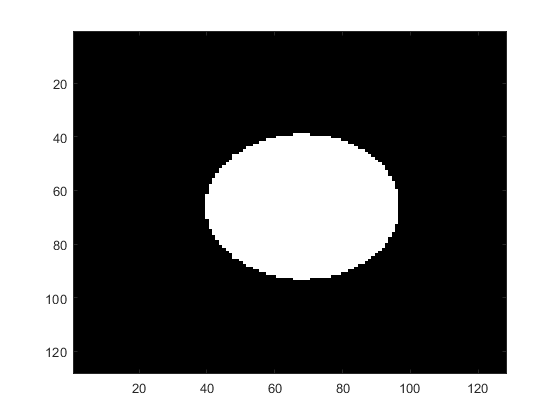


load('phantom2.mat')
figure;
imagesc(a);colormap(gray(128));

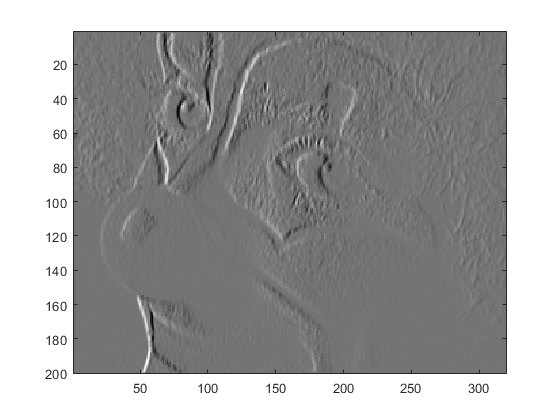

mx=[1 0 -1].*ones(3,1).*1/6; % mask

yclown=conv2(clown,mx,'same');
ya=conv2(a,mx,'same');

figure;
imagesc(yclown);colormap(gray(128));

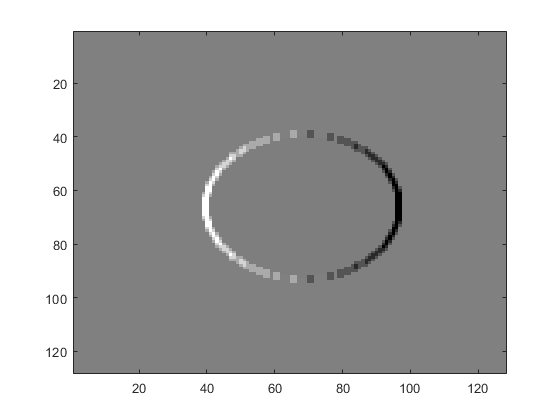

figure;
imagesc(ya);colormap(gray(128));

#### Extract a 1-dimensional image profile

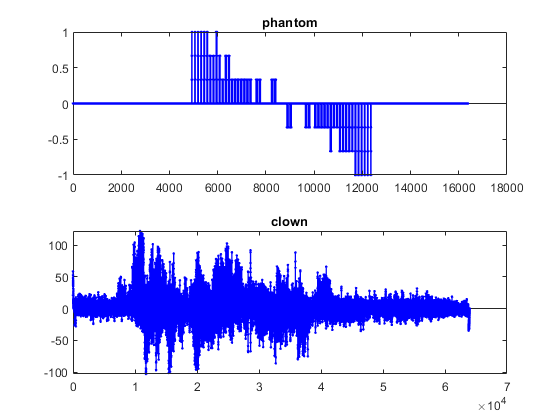

figure;
subplot(2,1,1)
stem(ya(:),'b.','LineWidth',1);title('phantom')

subplot(2,1,2)
stem(yclown(:),'b.','LineWidth',1);title('clown')

#### absolute value of the edge-strength only

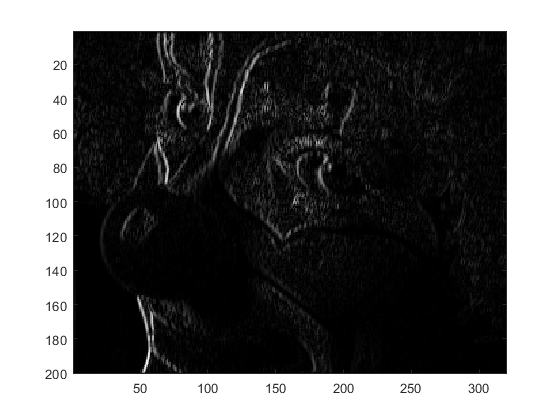

figure;
imagesc(abs(yclown));colormap(gray(128));

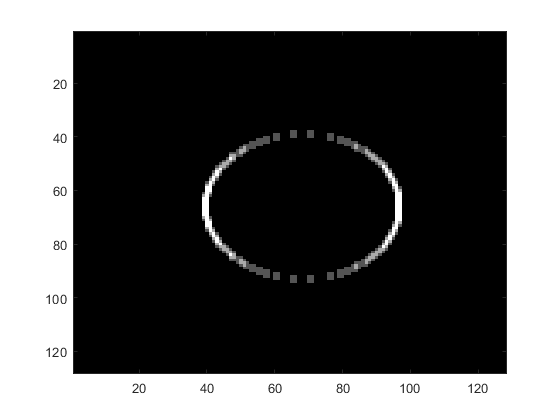

figure;
imagesc(abs(ya));colormap(gray(128));

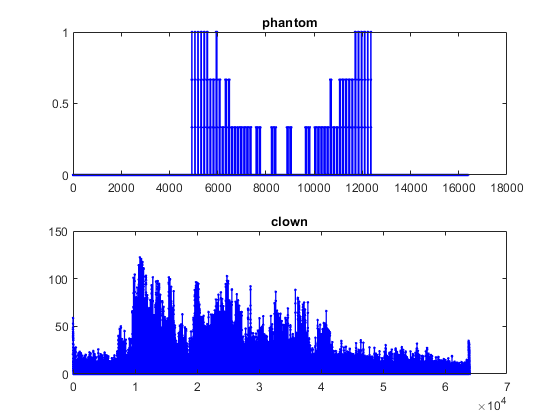


figure;
subplot(2,1,1)
stem(abs(ya(:)),'b.','LineWidth',1);title('phantom')

subplot(2,1,2)
stem(abs(yclown(:)),'b.','LineWidth',1);title('clown')

#### convolution kernel

my=mx'

my =     0.1667    0.1667    0.1667
         0         0         0
   -0.1667   -0.1667   -0.1667


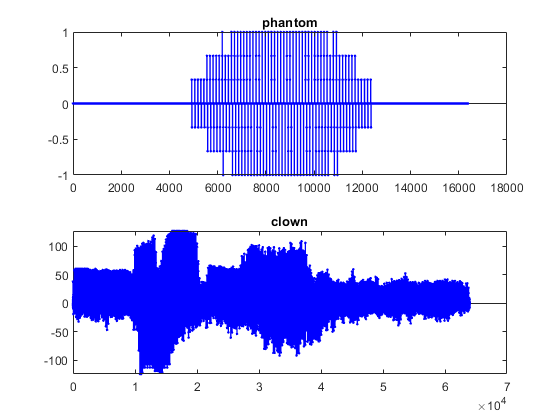

yclown_2=conv2(clown,my,'same');
ya_2=conv2(a,my,'same');

figure;
subplot(2,1,1)
stem(ya_2(:),'b.','LineWidth',1);title('phantom')

subplot(2,1,2)
stem(yclown_2(:),'b.','LineWidth',1);title('clown')

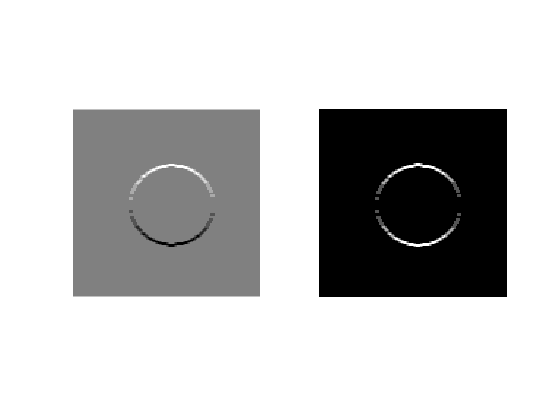


figure;
subplot(1,2,1)
imagesc(ya_2);colormap(gray(128));axis square; axis off;
subplot(1,2,2)
imagesc(abs(ya_2));colormap(gray(128));axis square; axis off;

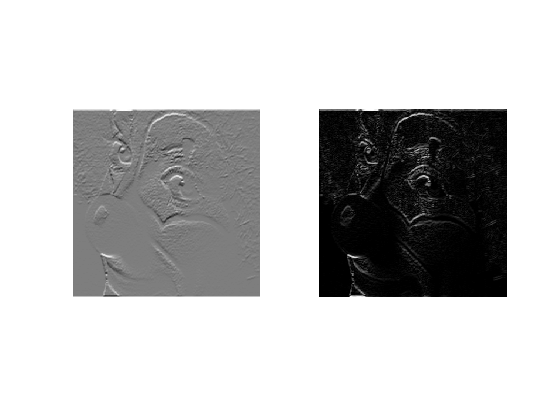


figure;
subplot(1,2,1)
imagesc(yclown_2);colormap(gray(128));axis square; axis off;
subplot(1,2,2)
imagesc(abs(yclown_2));colormap(gray(128));axis square; axis off;

#### combination of both masks

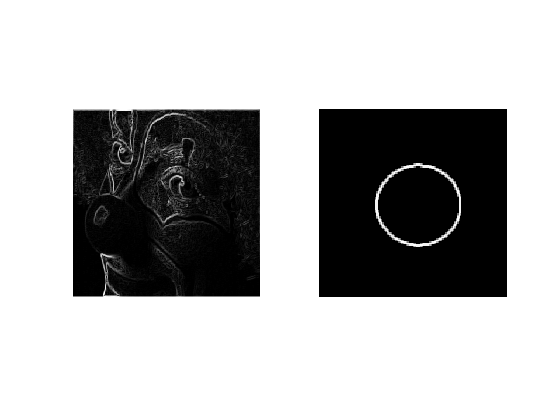

yclown_combined=sqrt(yclown_2.^2+yclown.^2);
ya_combined=sqrt(ya_2.^2+ya.^2);

figure;
subplot(1,2,1)
imagesc(yclown_combined);colormap(gray(128));axis square; axis off;
subplot(1,2,2)
imagesc(ya_combined);colormap(gray(128));axis square; axis off;

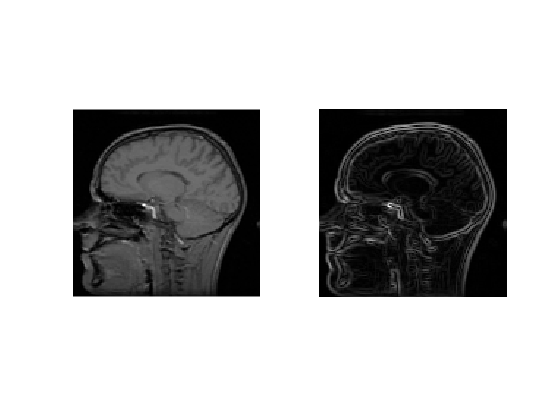


fid = fopen('head.128','r');
[x,npels] = fread(fid,[128,128],'uchar');
x = x';
fclose(fid);
figure;
subplot(1,2,1)
imagesc(x);colormap(gray);axis square;axis off;

xscan=conv2(x,mx,'same');
yscan=conv2(x,my,'same');
x_combined=sqrt(xscan.^2+yscan.^2);

subplot(1,2,2)
imagesc(x_combined);colormap(gray);axis square;axis off;

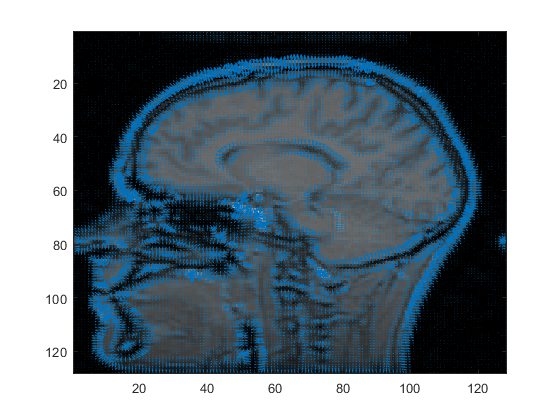

figure;
[xcord,ycord] = meshgrid(1:size(x,2),1:size(x,1)); 
imagesc(x);colormap(gray(128)); hold on
quiver(xcord,ycord,xscan,yscan,5);

## Scale-Space Decompositions and Estimators of Gradient

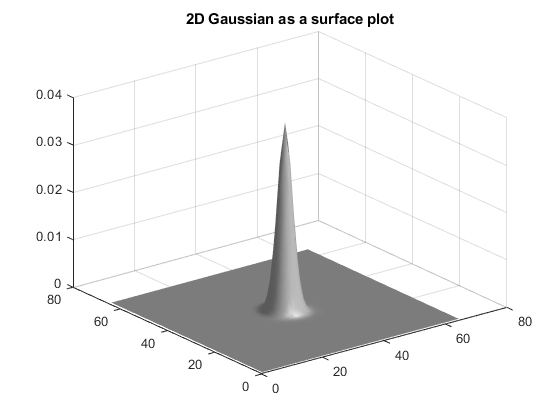

sigma = 2;
J = fspecial('gauss',[65,65],sigma);

[x,y] = meshgrid(1:size(J,2),1:size(J,1));

figure();
surfl(x,y,J)
shading interp
title('2D Gaussian as a surface plot');
colormap(gray(128));

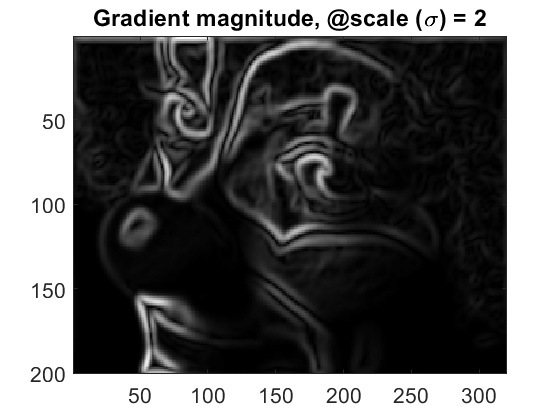



gx_s = conv2(yclown,J,'same');
gy_s = conv2(yclown_2,J,'same');

g_s = sqrt(gx_s.^2 + gy_s.^2);

gx_a = conv2(ya,J,'same');
gy_a = conv2(ya_2,J,'same');

g_a = sqrt(gx_a.^2 + gy_a.^2);

figure()
imagesc(g_s);colormap(gray(128));
title(['Gradient magnitude, @scale (\sigma) = ',num2str(sigma)]);
set(gca,'FontSize',16);

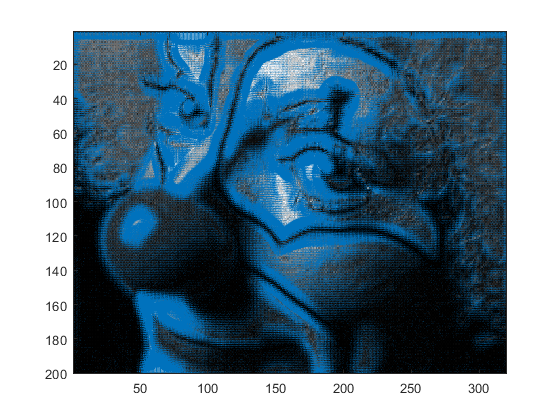


[x,y] = meshgrid(1:size(clown,2),1:size(clown,1)); 
figure;
imagesc(clown);colormap(gray(128)); hold on
quiver(x,y,gx_s,gy_s,5);

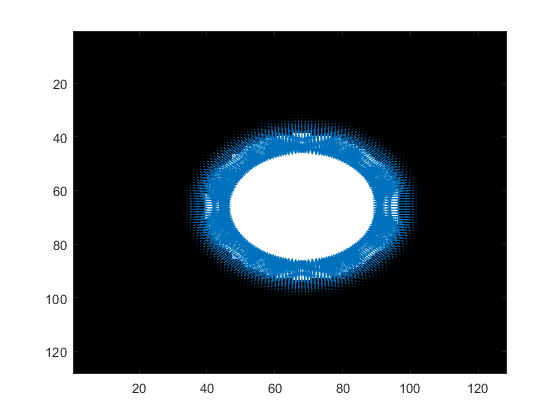


[x,y] = meshgrid(1:size(a,2),1:size(a,1)); 
figure;
imagesc(a);colormap(gray(128)); hold on
quiver(x,y,gx_a,gy_a,5);